Stabilità

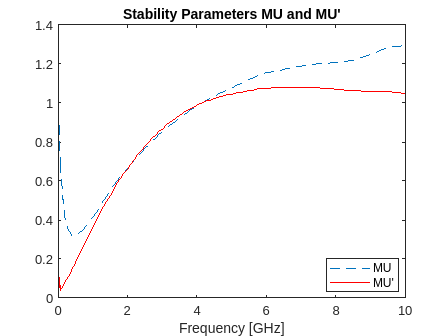

clear
clf

q_point = [8e-3 3]; %Ic VCE
op_freq = 1.6e9;
lin_freq = 3e7:10e6:5e9;

Z0=50; %ohm

bfp640 = read(rfckt.amplifier , ['BFP640/BFP640_w_noise_VCE_3.0V_IC_8.0mA.s2p']);
[s_par , freq] = extract(bfp640 , 'S_parameters');

[mu,muprime] = stabilitymu(s_par);
figure
plot(freq/1e9,mu,'--',freq/1e9,muprime,'r')
legend('MU',"MU'",'Location','Best') 
title("Stability Parameters MU and MU'")
xlabel('Frequency [GHz]')

gammas =0.3020*exp(-122.8*2*pi*i/360)

gammas = -0.1636 - 0.2539i

gammal =0.3993*exp(33.3*2*pi*i/360)

gammal = 0.3337 + 0.2192i

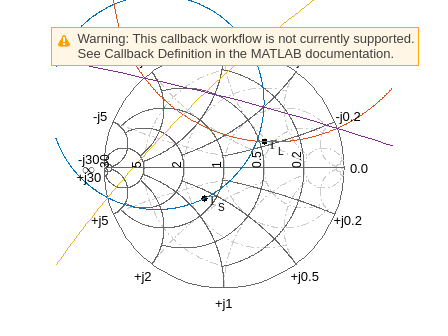


figure
sp = smithplot;
sp.GridType = 'YZ';
circle(bfp640 , op_freq , "Ga" , 22 , 'Gp' , 25 , 'Stab' , 'In' , 'Stab' , 'Out' , sp);
hold on
plot(gammas,'k.','MarkerSize',16);
text(real(gammas)+0.05,imag(gammas)-0.05,'\Gamma_{S}','FontSize', 12, ...
    'FontUnits','normalized');
plot(gammal,'k.','MarkerSize',16);
text(real(gammal)+0.05,imag(gammal)-0.05,['\Gamma_{L}'],'FontSize', 12, ...
    'FontUnits','normalized');
hold off

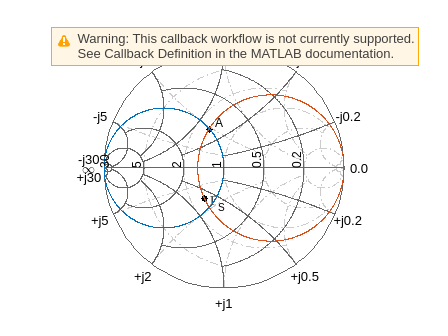


figure
sp1 = smithplot;
sp1.GridType = 'YZ';

Za = (0.641+0.474j)*Z0;

circle(bfp640 , op_freq , "G" , 1 , 'R' , real(gamma2z(gammas , 1)) , sp1);
hold on
plot(gammas,'k.','MarkerSize',16);
text(real(gammas)+0.05,imag(gammas)-0.05,'\Gamma_{S}','FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Za),'k.','MarkerSize',16);
text(real(z2gamma(Za))+0.05,imag(z2gamma(Za))+0.05,'A','FontSize', 12, ...
    'FontUnits','normalized');
hold off

imag(Za)

ans = 23.7000

C_shunt = 1/(abs(imag(1/Za))*2*pi*op_freq)

C_shunt = 6.6688e-09

C_series = 1/(abs(imag(gamma2z(gammas) - Za))*2*pi*op_freq)

C_series = 2.3913e-12




input_match = rfckt.cascade('Ckts', ...
    {rfckt.shuntrlc('L',C_shunt),rfckt.seriesrlc('C',C_series)});

Output match




figure
sp2 = smithplot;
sp2.GridType = 'YZ';


Zb = (1+1.083j)*Z0

Zb = 50.0000 + 54.1500i

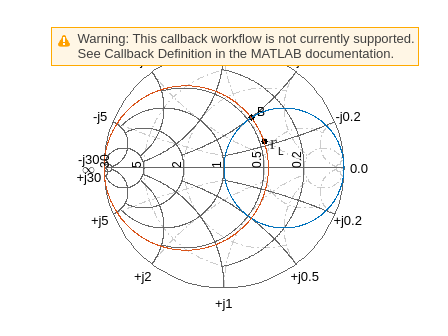


circle(bfp640 , op_freq , "R" , 1 , "G" , real(1/gamma2z(gammal , 1)) , sp2);
hold on
plot(gammal,'k.','MarkerSize',16);
text(real(gammal)+0.05,imag(gammal)-0.05,['\Gamma_{L}'],'FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Zb),'k.','MarkerSize',16);
text(real(z2gamma(Zb))+0.05,imag(z2gamma(Zb))+0.05,'B','FontSize', 12, ...
    'FontUnits','normalized');

hold off

imag(gamma2z(gammal,1) - Zb/50);
L_shunt = abs(imag(1/gamma2z(gammal,1) - 50/Zb))/(Z0*2*pi*op_freq)

L_shunt = 5.1411e-13

L_series = abs(imag(Zb))/(2*pi*op_freq)

L_series = 5.3864e-09




output_match = rfckt.cascade('Ckts', ...
  {rfckt.shuntrlc('C',L_shunt),rfckt.seriesrlc('L',L_series)});

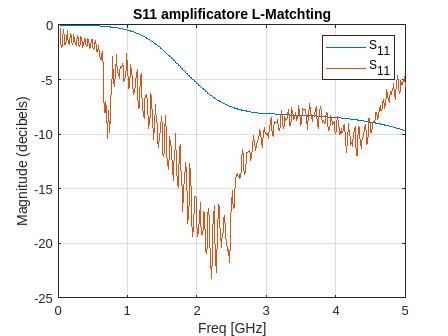

LNA = rfckt.cascade('ckts', ...
    {input_match,bfp640,output_match});

analyze(LNA,lin_freq);

LNA_sper = read(rfckt.amplifier , 'LNA_L_TAMB.s2p');
analyze(LNA_sper,lin_freq);

figure,plot(LNA,'S11','dB');
title("S11 amplificatore L-Matchting")
hold on
plot(LNA_sper,'S11','dB');
hold off

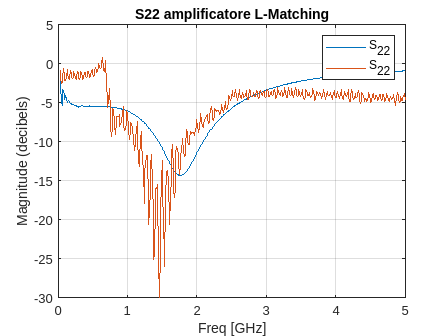


figure,plot(LNA,'S22','dB');
title("S22 amplificatore L-Matching")
hold on
plot(LNA_sper,'S22','dB');
hold off

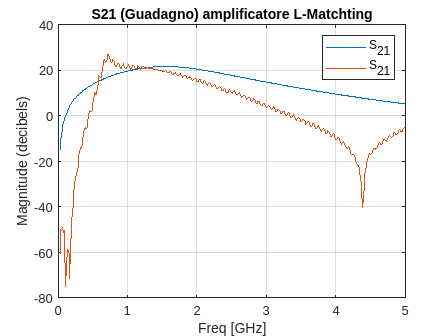


figure,plot(LNA,'S21','dB');
title("S21 (Guadagno) amplificatore L-Matchting")
hold on
plot(LNA_sper,'S21','dB');
hold off